# Lesson 14 TCLab: PI Control Tuning

**Objective: Use the IMC and ITAE tuning correlations for PI control of the TCLab. Also compare the integral absolute error difference between setpoint and measured temperature for a setpoint change from **$23^\circ\text{C}$** to **$60^\circ\text{C}$.

Each process has different characteristics and requirements. The same unit operation at different locations within the same plant can have different control characterstics due to climate, construction, and other variances. In addition, different processes have different objectives: the temperature controller of an oven may seek to achieve the target temperature as fast as possible while the controller for a flowmeter may seek to avoid oscillation and chattering.

**Tuning Correlations** provide rough guidance for PID tuning parameters. After using a tuning correlation, the parameters should be further tuned with the specific objective in mind to balance how agressive the response is, and resulting oscillation. This delicate process of adjusting is similar to *tuning* an instrument where fine adjustments are made to achieve the desired pitch.

Common tuning correlations for PI control are the IMC (Internal Model Control) and ITAE (Integral of Time-weighted Absolute Error) methods. Use the IMC and ITAE setpoint tracking tuning correlations with FOPDT parameters ($
K_c$, $\tau_p$, $\theta_p$) determined from the TCLab graphical fitting or TCLab regression exercises.

**IMC Aggressive Tuning**


$$\tau_c = \max \left( 0.1 \tau_p, 0.8 \theta_p \right)$$



$$K_c = \frac{1}{K_p}\frac{\tau_p}{\left( \theta_p + \tau_c \right)} \quad \quad \tau_I = \tau_p$$


**ITAE Tuning**


$$K_c = \frac{0.586}{K_p}\left(\frac{\theta_p}{\tau_p}\right)^{-0.916} \quad \tau_I = \frac{\tau_p}{1.03-0.165\left(\theta_p/\tau_p\right)}$$


Fill in the values of $K_c$, $\tau_I
$, and the PI equation in the code below. Run both tuning correlations separately with the TCLab to determine the integral absolute error difference between the setpoint and measured temperature.

Kp = 0.9;
taup = 175;
thetap = 15;

% IMC Tuning
tauc = max(0.1 * taup, 0.8 * thetap)

tauc = 17.5000

Kc = 1 / Kp * taup / (thetap + tauc)

Kc = 5.9829

tauI = taup

tauI = 175


% ITAE Tuning
Kc =  

Kc = 6.1799

tauI =  

tauI = 172.2683

## PI Control Simulator

A PI Control simulator can be used to anticipate the control performance with changes in control tuning parameters, $K_c$ and $\tau_I
$. The IMC and ITAE recommended values can be tested before implementing the closed loop control with the TCLab. Adjust the slider bars  to see the updated plots and calculated integral absolute error.

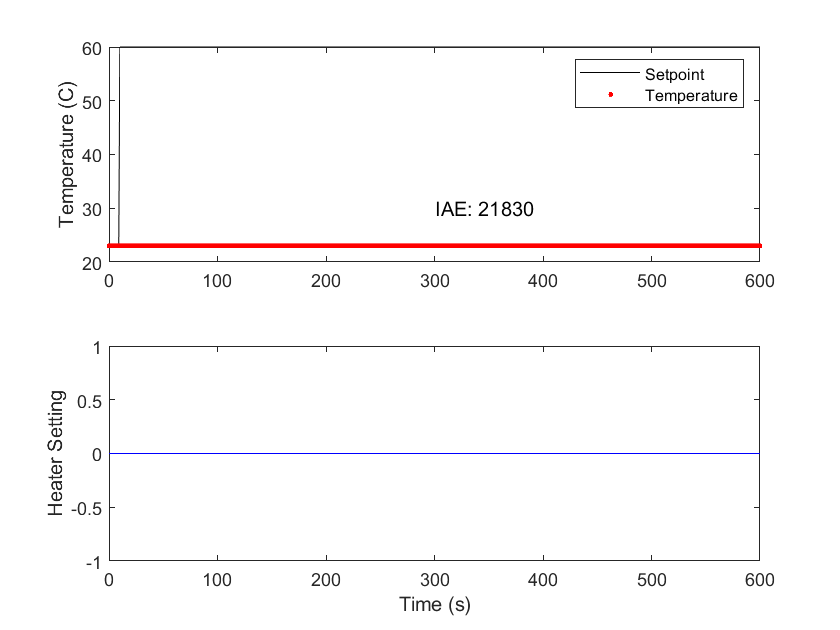

Kc = 0;
tauI = 180;
pidPlot(Kc, tauI)

## PI Control Validation 

Use either MATLAB or Simulink in the following sections to test your PID Tuning.

### Simulink

Simulink is a MATLAB-based graphical programming environment for modeling, simulating and analyzing multidomain dynamical systems. Its primary interface is a graphical block diagramming tool and a customizable set of block libraries. The other TCLab Activity in this section explores tuning using Simulink.

### MATLAB

viewSolution(false)

Using the FOPDT parameters ($
K_p$, $\tau_p$, $\theta_p$) determined from the TCLab graphical fitting or TCLab regression exercises, use IMC Agressive or ITAE tuning to find $K_c$, $\tau_I
$ for the controller. Then, program a PI controller and change the setpoint of the TCLab unit from $23^\circ\text{C}$ to $60^\circ\text{C}$ over 600 seconds. Plot the resulting temperature and heater settings. Also report the integral of error

% ITAE Solution
% process model
Kp = 0.9;
taup = 175.0;
thetap = 15.0;

% -----------------------------
% Calculate Kc,tauI,tauD (ITAE)
% -----------------------------
Kc = (0.586/Kp)*(thetap/taup)^(-0.916)

Kc = 6.1799

tauI = taup/(1.03-0.165*(thetap/taup))

tauI = 172.2683

tauD = 0

tauD = 0

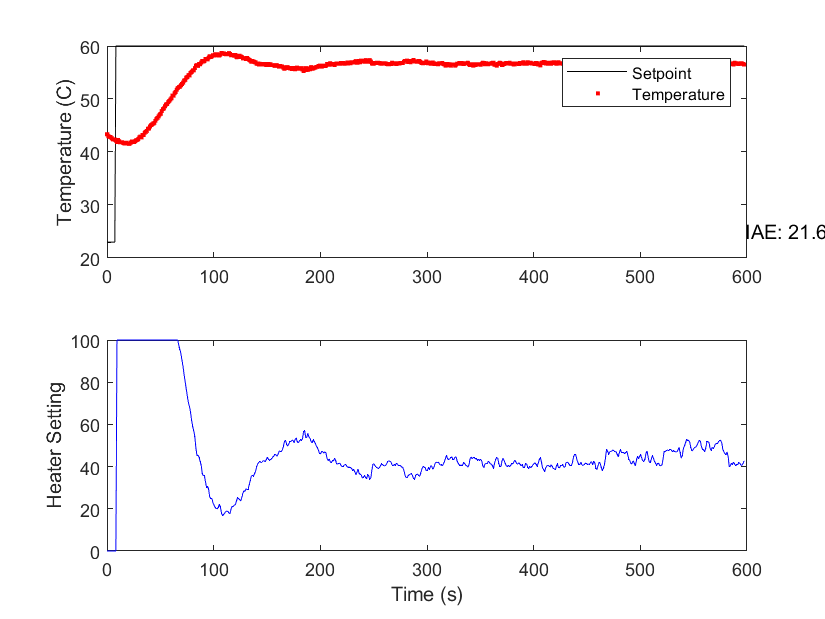

params = [Kc tauI tauD];

% create arrays for loop
n = 600;
tm_ = linspace(0, n, n+1);
T1_ = zeros(n, 1);
Q1_ = zeros(n, 1);
SP1_ = ones(n, 1) * 23.0;
SP1_(10:end) = 60.0;
ierr = 0;

% loop through control with tclab" + newline + ...
lab = tclab;
T1_(1) = lab.T1;
tic
figure
hold on
for i = 2:n-1
    T1_(i) = lab.T1;
    tm_(i) = toc;
    [Q1_(i), P, ierr, D] = pidController(params, SP1_(i), T1_(i), T1_(i-1), ierr, tm_(i) - tm_(i-1));
    lab.Q1(Q1_(i));

    % plot
    subplot(2,1,1)
    plot(tm_(1:i), SP1_(1:i), 'k-', 'DisplayName','Setpoint')
    hold on
    plot(tm_(1:i), T1_(1:i), 'r.', 'DisplayName','Temperature')
    hold off
    text(i-1, 25, 'IAE: '+string(ierr))
    legend
    ylabel('Temperature (C)')
    subplot(2,1,2)
    plot(tm_(1:i), Q1_(1:i), 'b-')
ylabel('Heater Setting')
xlabel('Time (s)')

% wait
pause(mod((1-toc), 1))
         end

## **Optimization of PI Tuning (not required)**

Optimization is another method for tuning PID controllers. Using closed-loop data and a model of the process (e.g. FOPDT or ARX), candidate PID parameters can be simulated to determine the best performance. The following 3D plot is the average integral absolute error for temperature and heater movements for the TCLab with KcKc and τIτI parameters. The lowest objective is the best performance at $K_c$=10.0 and $\tau_I
$=55.0 sec. More information on optimization is provided in the [**Design Optimization Course**](https://apmonitor.com/me575) and the [**Machine Learning and Dynamic Optimization Course**](https://apmonitor.com/do).

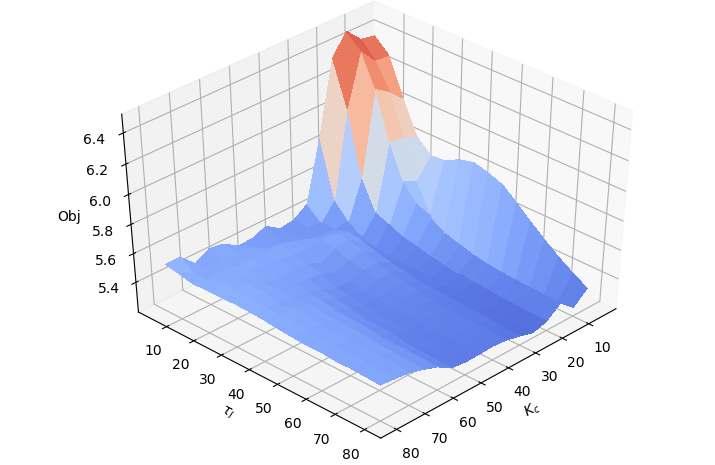

function dydt = fopdt(t, y, u)
    dydt = (-(y-23.0) + 0.9 * u)/175.0;
end

function pidPlot(kC, tauI)
    n = 601;  % number of measurements
    op_hi = 100;
    op_lo = 0;
    
    tm_ = linspace(0, n-1, n);
    P_ = zeros(1, n);
    I_ = zeros(1, n);
    e_ = zeros(1, n);
    OP_ = zeros(1, n);
    PV_ = ones(1, n) * 23.0;
    SP_ = ones(1, n) * 23.0;
    SP_(11:end) = 60.0;
    iae = 0.0;
    dt = tm_(2) - tm_(1);
    
    % simulate PID
    for i=1:n-1
        e_(i) = SP_(i) - PV_(i);
        iae = iae + e_(i) * dt;
        
        P_(i) = kC * e_(i);
        I_(i) = kC/tauI * iae;
        
        OP_(i) = P_(i) + I_(i);
        
        % Anti-reset windup
        if OP_(i) > op_hi  % check upper limit
            OP_(i) = op_hi;
            iae = iae - e_(i) * dt; % anti-reset windup
        end
        if OP_(i) < op_lo  % check lower limit
            OP_(i) = op_lo;
            iae = iae - e_(i) * dt; % anti-reset windup
        end
        
        % Implement time delay
        if tm_(i)-15.0 < 0
            iop = OP_(1);  % iop is the op for each time point i with dead time taken into account
        else
            iop = interp1(tm_, OP_, tm_(i)-15.0);
        end
        
        % Simulate process
        ts = [tm_(i),tm_(i+1)];
        [~, y] = ode45(@(t, y) fopdt(t,y,iop), ts, PV_(i));
        PV_(i+1) = y(end);
    end
    
    figure()
    subplot(2,1,1)
    plot(tm_, SP_, 'k-', 'DisplayName','Setpoint')
    hold on
    plot(tm_, PV_, 'r.', 'DisplayName','Temperature')
    text(300, 30, 'IAE: '+string(iae))
    legend
    ylabel('Temperature (C)')
    subplot(2,1,2)
    plot(tm_, OP_, 'b-')
    ylabel('Heater Setting')
    xlabel('Time (s)')
end

function [op, P, I, D] = pidController(params, sp, pv, pv_last, I, dt)
    % PID controller. ubias of 0 and output range of 0 to 100 assumed
    % INPUTS
    % params (array): controller constants for PID controller
    %     kC: controller gain
    %     TauI: integral time constant
    %     TauD: derivative time constant
    % sp: setpoint of controller
    % pv: process value
    % pv_last: previous process value
    % ierr: integral of error
    % dt: time step between measurements
    % OUTPUTS
    % op: controlled value setting
    % P: Proportional portion of PID equation
    % I: integral portion of the PID equation
    
    % unpack params
    kC = params(1);
    tauI = params(2);
    tauD = params(3);
    
    % calculate PID equation
    e = sp - pv;
    dedt = (pv - pv_last)/dt;
    
    P = kC * e;
    I = I + kC/tauI * e * dt;
    D = kC * tauD * dedt;
    op = P + I - D;
    
    % anti-reset windup
    % Anti-reset windup
    if op > 100  % check upper limit
        op = 100;
        I = I - kC/tauI * e * dt; % anti-reset windup
    elseif op < 0  % check upper limit
        op = 0;
        I = I - kC/tauI * e * dt; % anti-reset windup
    end
end

## Solution

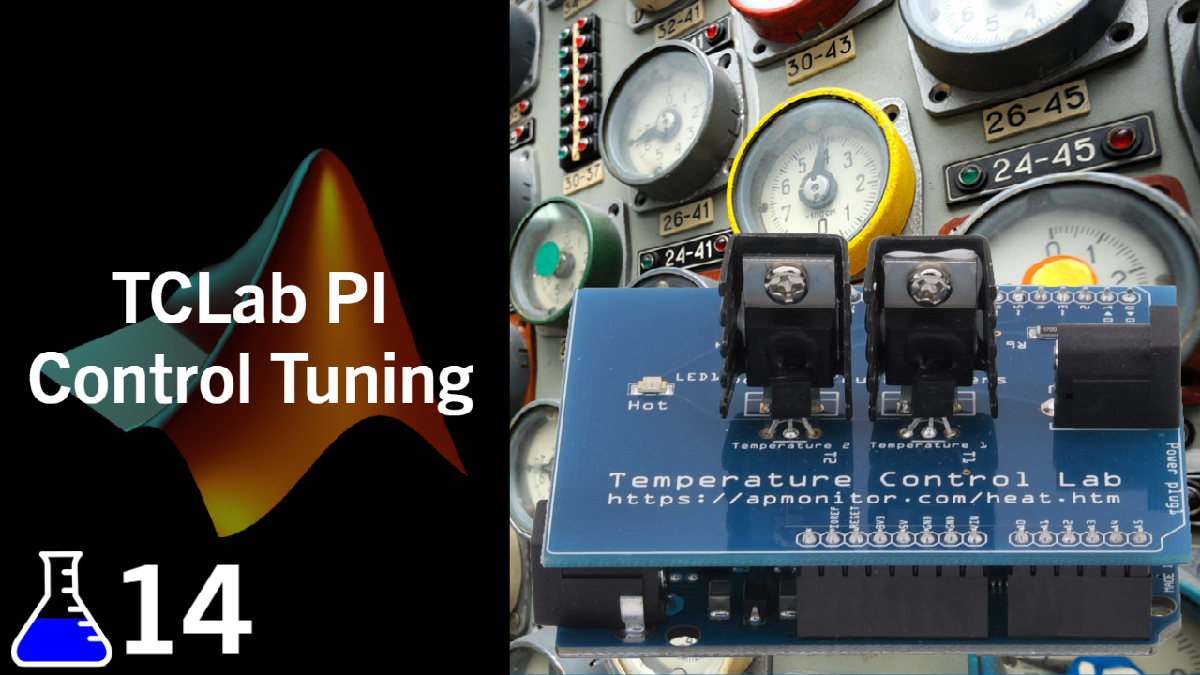

### View Solution

function viewSolution(view)
if view
	disp("% ITAE Solution" + newline + ...
	     "% process model" + newline + ...
	     "Kp = 0.9;" + newline + ...
	     "taup = 175.0;" + newline + ...
	     "thetap = 15.0;" + newline + ...
	     "" + newline + ...
	     "% -----------------------------" + newline + ...
	     "% Calculate Kc,tauI,tauD (ITAE)" + newline + ...
	     "% -----------------------------" + newline + ...
	     "Kc = (0.586/Kp)*(thetap/taup)^(-0.916)" + newline + ...
	     "tauI = taup/(1.03-0.165*(thetap/taup))" + newline + ...
	     "tauD = 0" + newline + ...
	     "params = [Kc tauI tauD];" + newline + ...
	     "" + newline + ...
	     "% create arrays for loop" + newline + ...
	     "n = 600;" + newline + ...
	     "tm_ = linspace(0, n, n+1);" + newline + ...
	     "T1_ = zeros(n, 1);" + newline + ...
	     "Q1_ = zeros(n, 1);" + newline + ...
	     "SP1_ = ones(n, 1) * 23.0;" + newline + ...
	     "SP1_(10:end) = 60.0;" + newline + ...
	     "ierr = 0;" + newline + ...
	     "" + newline + ...
	     "% loop through control with tclab" + newline + ...
	     "lab = tclab;" + newline + ...
	     "T1_(1) = lab.T1;" + newline + ...
	     "tic" + newline + ...
	     "figure" + newline + ...
	     "hold on" + newline + ...
	     "for i = 2:n-1" + newline + ...
	     "    T1_(i) = lab.T1;" + newline + ...
	     "    tm_(i) = toc;" + newline + ...
	     "    [Q1_(i), ierr] = pidController(params, SP1_(i), T1_(i), T1_(i-1), ierr, tm_(i) - tm_(i-1));" + newline + ...
	     "    lab.Q1(Q1_(i));" + newline + ...
	     "    " + newline + ...
	     "    % plot" + newline + ...
	     "    subplot(2,1,1)" + newline + ...
	     "    plot(tm_(1:i), SP1_(1:i), 'k-', 'DisplayName','Setpoint')" + newline + ...
	     "    hold on" + newline + ...
	     "    plot(tm_(1:i), T1_(1:i), 'r.', 'DisplayName','Temperature')" + newline + ...
	     "    hold off" + newline + ...
	     "    text(i-1, 25, 'IAE: '+string(ierr))" + newline + ...
	     "    legend" + newline + ...
	     "    ylabel('Temperature (C)')" + newline + ...
	     "    subplot(2,1,2)" + newline + ...
	     "    plot(tm_(1:i), Q1_(1:i), 'b-')" + newline + ...
	     "    ylabel('Heater Setting')" + newline + ...
	     "    xlabel('Time (s)')" + newline + ...
	     "    " + newline + ...
	     "    % wait" + newline + ...
	     "    pause(mod((1-toc), 1))" + newline + ...
	 "end")
end
end
